# Part 4: Bitplane Slicing

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture4 - Point Processing

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

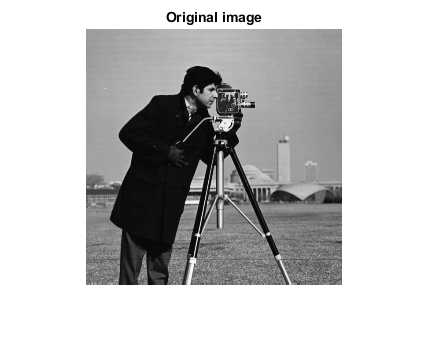

% read and display input image
I = imread('images/cameraman.tif'); 
if(size(I,3) == 3) % convert to grayscale if not
    I = rgb2gray(I);
end
imshow(I), title('Original image');

## Bitplane slicing

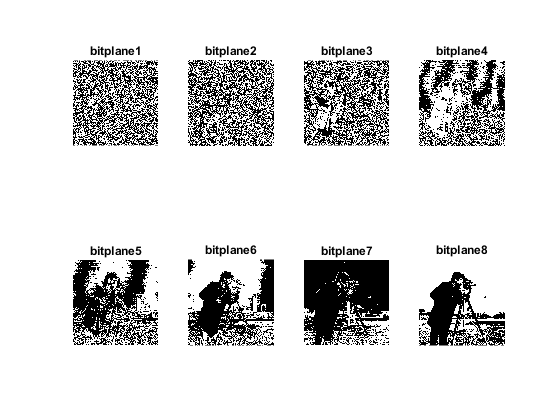

% extract and display bitplanes
figure
for i = 1:8
    Ib = bitget(I,i);
    subplot(2,4,i), imshow(Ib,[]), title(strcat('bitplane ', num2str(i)));
end

## Reconstruction from bitplanes

*1. reconstruct using all bitplanes*

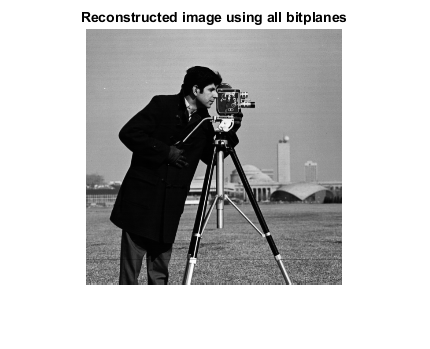

Ir = zeros(size(I));
for i = 1:8
    Ir = Ir + 2^(i-1)*double(bitget(I,i));
end
figure, imshow(Ir,[]), title('Reconstructed image using all bitplanes')

% check wether it is reconstructed correctly
Idif = uint8(Ir)-I;
sum(Idif(:))

ans = 0

*2. reconstruct using 6, 7, 8. bitplanes*

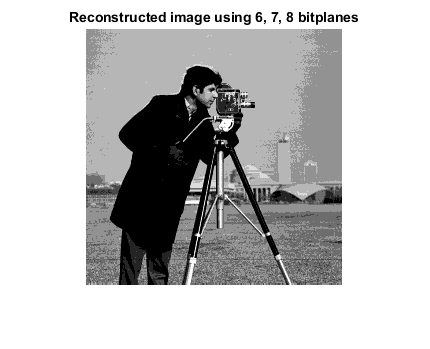

Ir = zeros(size(I));
for i = 6:8
    Ir = Ir + 2^(i-1)*double(bitget(I,i));
end
figure, imshow(Ir,[]), title('Reconstructed image using 6, 7, 8 bitplanes')

**Hiding information into bitplanes**

A very simple example of image steganography

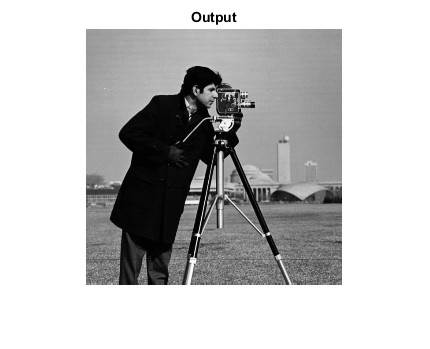

Itest = imread('circles.png'); %read a totally different image into first bitplane
for i = 2:8 %the other bitplanes are from the cameraman image
    Itest = Itest + 2^(i-1)*double(bitget(I,i));
end
figure, imshow(Itest,[]), title('Output')

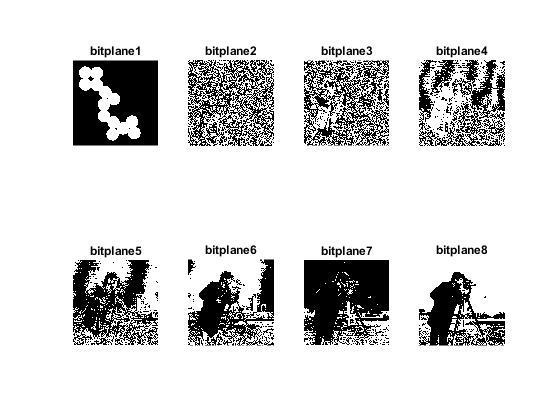

% extract and display bitplanes
figure
for i = 1:8
    Ib = bitget(Itest,i);
    subplot(2,4,i), imshow(Ib,[]), title(strcat('bitplane ', num2str(i)));
end